# MATLAB bootcamp

## Introduction

#### Interface and basic commands

Three main windows:

- Command window

- Workspace

- Current working directory:

Find current working directory

pwd

Semicolon (**;**) used at the end of a command line to **suppress** **output** display:

pwd;

Set current working directory, mine is:

cd C:\Users\mydam\Desktop\Teaching\matlab\Matlab
% cd C:\Users\mydam\Desktop\test

Clear command window

clc

Clear all variables in the workspace

clear

Clear specific variables only

View files in the directory

dir

Delete files in the directory

#### Editor

- Home -> New Script : Normal text editor for MATLAB, no interaction

- Home -> New Live Script : Script + Formatted text + Results in a single environment

#### Comments

Percentage symbol (%) tells the processing to skip the current (commented) line and continues on the next (similar to LateX).

% this is a block of text within a command area
% often used to comment
% or to skip a command
t = 3; % set t equal to 3

Shortcuts: 

- Comment out: CLTR + R

- Uncomment: CLTR + T

#### Breaking down long codes into several lines

x = 10;
y = x + exp(x) + sqrt(x) - ... % three dots tell Matlab to continue on the next line
    x^2 + 2*x

y = 2.1960e+04

y

y = 2.1960e+04

#### Getting help

Help with function

% help mean
help floor

 floor  Round towards minus infinity.
    floor(X) rounds the elements of X to the nearest integers
    towards minus infinity.
 
    See also round, ceil, fix.

    Documentation for floor
    Other functions named floor



floor(1/3)

ans = 0

Help with toolbox

% help stats          % returns functions available in the stats toolbox

Pull out documentation on a function/toolbox

doc stats

To view the whole documentation 

doc

#### Discovering MATLAB via demos

demo

## Basic input

### Variable assignment

Name of variable has to be different from predefined functions/variables in MATLAB. To check if a name is already taken:

% which i
which z

'z' not found.


Assignment of values to variable via the equal sign:

m = 5 + 7

m = 12

z = 2

z = 2

q = z + x

q = 12

Later assignment overwrites previous ones.

i = 2;
i

i = 2

clear i  % clear assignment
i

ans = 0.0000 + 1.0000i

Variable names are **case sensitive**

z1 = 23;
Z1 = 12;
z1 + Z1

Variable names must** begin with a letter**, and contain** no math operators** (:,-,+,*,etc.)

- Valid names: myVar, my_var1, MyVar1, global_1

- Invalid names: _myvar, 1Var, X+1, global

Variable names contain **none of the following keywords**:

### Vectors and Matrices

#### Colon operator

Generates a row vector of numbers in ascending (default) or descending orders.

x = 1:5  % first operand: starting value; second: ending value; step = 1 by default

x =      1     2     3     4     5


Suppose we want to specify the steps also

y = 1:0.5:5 % the operand in the middle specifies the steps of the sequence

y =     1.0000    1.5000    2.0000    2.5000    3.0000    3.5000    4.0000    4.5000    5.0000


We can also generate a descending sequence (steps specification required)

z = 5:-1:-5 

z =      5     4     3     2     1     0    -1    -2    -3    -4    -5


If we don't specify steps

t = 5:-5


t =

  1×0 empty double row vector



#### Vectors

Three ways to generate a row vector:

x = 1:5

x =      1     2     3     4     5


y = [1,2,3,4,5]

y =      1     2     3     4     5


z = [1 2 3 4 5]

z =      1     2     3     4     5


The function length`() `gives the length of the vector, `size()` gives the dimension of the matrix (both row and column indices)

size(x)

ans =      1     5


length(x)

ans = 5

Column vectors

v = [1; 2; 3; 4; 5]

v =      1
     2
     3
     4
     5


size(v)

ans =      5     1


Inside the square brackets, a semicolon signifies a new row.

#### Matrices

A 3x3 matrix

L = [1 2 3; 4 5 6; 8 9 1]

L =      1     2     3
     4     5     6
     8     9     1


#### Some matrix operations

The **determinant** of L is

det(L)

ans = 27

We can compute its **inverse **since it is not singular

L_inv = inv(L)

L_inv =    -1.8148    0.9259   -0.1111
    1.6296   -0.8519    0.2222
   -0.1481    0.2593   -0.1111


**Some special matrices**

Matrices of zeros

x = zeros
y = zeros(4)
C = zeros(2,3)

Matrices of ones

A = ones(3)

x = 0

B = ones(2,3)

y =      0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


Identity matrices

eye(4)

C =      0     0     0
     0     0     0


% eye(4,1)

Empty matrices 

A = []

#### Concatenation

L = [1 2 3; 4 5 6; 8 9 1]
v = [0.5 1 1]

Vertical concatenation

M = [L;v]

ans =      1
     0
     0
     0


Horizontal concatenation

% N = [L v]
% P = [L transpose(v)]
P = [L, v']

L =      1     2     3
     4     5     6
     8     9     1


#### Accessing elements of matrices

Extract a row

L = [1 2 3; 4 5 6; 7 8 9]

v =     0.5000    1.0000    1.0000


Extract an entire row

row3 = L(3,:)

M =     1.0000    2.0000    3.0000
    4.0000    5.0000    6.0000
    8.0000    9.0000    1.0000
    0.5000    1.0000    1.0000


The colon operator (:) means *all elements in that dimension*

Extract a column

L = [1 2 3; 4 5 6; 7 8 9]

P =     1.0000    2.0000    3.0000    0.5000
    4.0000    5.0000    6.0000    1.0000
    8.0000    9.0000    1.0000    1.0000


col2 = L(:,2)

Extract a single element from a matrix

L = [1 2 3; 4 5 6; 7 8 9]

L =      1     2     3
     4     5     6
     7     8     9


row3_col2 = L(3,2)

Extract a single element  from a vector

col2(3)

Extract a submatrix from a matrix

M = randn(4)

L =      1     2     3
     4     5     6
     7     8     9


N = M(2:4,[2 3]) % extract from M rows 2-4, columns 2,3

col2 =      2
     5
     8


## Basic maths

### Operators

- Addition:  x + y = $x+y$

-  Subtraction: x - y = $x-y$

- Multiplication: x * y = $xy$

- Division (left): x / y = $\frac{x}{y}$

- Division (right): x \ y = $\frac{y}{x}$

- Exponential : x ^ y = $x^y$

Care must be taken when $x$ and/or $y$ are not scalars.

### Matrix addition and subtraction

In linear algebra, these operations require that the two matrices have the same dimension.  

x = [1 2; 3 4]
y = [5 6; 7 8]
x + y

Nevertheless, the following operations are also allowed in MATLAB. Can you guess what they result in?

x + 3;
x + y(:,1);
x + y(1,:);

### Matrix multiplication

Matrices must be conformable in order to multiplication to work

x * y;

M =    -1.2075    1.0347   -0.7873   -0.8095
    0.7172    0.7269    0.8884   -2.9443
    1.6302   -0.3034   -1.1471    1.4384
    0.4889    0.2939   -1.0689    0.3252


% x * y(1,:) % produces an error

N =     0.7269    0.8884
   -0.3034   -1.1471
    0.2939   -1.0689


x * y(:,1);

### Dot operations

The dot operator (.) signifies element-wise operations.

Compare

x

x =      1     2
     3     4


y

y =      5     6
     7     8


x .* y

ans =      6     8
    10    12


% x * y

### Transpose

The transpose of a matrix is either obtained by the function `transpose` or by the **' **operator. 

transpose(x)
x'

## Basic functions

#### length 

This function returns the *maximum dimension* of a matrix. That is, if A is N-by-K matrix, then `length(A)` returns max {N,K}.

A = [2 3; 4 5; 6 7]
length(A)
length(A(1,:))

#### size

This function returns the dimension of a matrix. 

A = [2 3; 4 5; 6 7]
size(A)

To extract the number of rows and columns separately:

[rowA, colA] = size(A)

#### sum 

This function computes the sum of each column of a matrix, returning a row vector

A = [2 3; 4 5; 6 7]

x =      1     2
     3     4


sum(A)

y =      5     6
     7     8


sum(A,1)

ans =      5    12
    21    32


Can we sum by row? 

sum(A,2)        % the second argument specifies the dimension along which the sum is performed   

Can we sum all elements of a matrix?

sum(sum(A))

#### max, min

Likewise, these operators search for the max/min value of each column of a matrix. The result is a row vector of length equal to the number of columns of the matrix

A = [1 2; 4 3; 5 9]

A =      2     3
     4     5
     6     7


maxA = max(A)

ans = 3

size(A)

ans = 2

size(max(A))

To compute extremal values along the row

max(A,[],2) 

A =      2     3
     4     5
     6     7


max(A')

ans =      3     2


It is also possible to report the position/index of the minimal/maximal value

[minA, indmin] = min(A) 

rowA = 3

colA = 2

Note that when the extremal values are not unique, MATLAB will report the index of the first one.

#### prod

Returns product of elements of each column of a matrix. It is possible to multiply elements of each row by specifying the dimension to multiply across. Compare

A = [1 2; 4 3; 5 9];

A =      2     3
     4     5
     6     7


prod(A);    % by column

ans =     12    15


prod(A,1);  % by column

ans =     12    15


prod(A,2);  % by row

#### cumsum, cumprod, cummax, cummin

The first two functions compute the cumulative sum and product of a matrix (column-by-column by default)

The last two compute the cumulative max and min.

Examples:

x = [1 3 2 0 9 6]
cumsum(x)
cummin(x)
cummax(x)

When the argument is a matrix instead of a vector, each of the above operations is performed along each column of the matrix.

A = [1 2; 4 3; 5 9]

A =      1     2
     4     3
     5     9


cumsum(A)

maxA =      5     9


cummin(A)

ans =      3     2


cummax(A)

ans =      1     2


#### exp

Computes the exponential of a matrix (element-by-element)

#### log

Computes the natural logarithm of a matrix (element-by-element)

#### sqrt

Computes the square root of a matrix (element-by-element)

#### mean

Computes the mean of each column of a matrix

C = randn(4,3)  % generate a 4x3 matrix of standard normal random numbers
mean(C)

Of course we can also compute the row averages

mean(C,2)

minA =      1     2


indmin =      1     1


#### var, std

Compute the sample variances (`var`) and standard deviations (`std`) of each column

n = 10000;
x = randn(n,4); % generate a nx4 matrix of standard normal numbers
xbar = mean(x)
var(x)
std(x)

NB: option to exclude missing values in the computation

#### cov

`cov` computes the sample covariance matrix.

Clearly if x is a vector then var(x) = cov(x). It is a symmetric matrx that gives the variance of each column vector along the principal diagonal, and the covariances off the diagonal.

D = rand(3)
col1 = D(:,1); col2 = D(:,2); col3 = D(:,3);
cov(D)
cov12 = cov(col1,col2)
% cov13 = cov(col1,col3)
% cov23 = cov(col2,col3)

#### skewness, kurtosis

`skewness` and `kurtosis` compute the sample skewness and kurtosis of a matrix (column by column)

n = 10; m = 10000;
X = randn(n,3);
Y = randn(m,3);
skewness(X)
skewness(Y)
kurtosis(X) % recall that the skewness for a standard normal distribution is 3
kurtosis(Y) 

## Logical Operators

### Main logical operators

- Greater than : >

- Greater than or equal to: >=

- Less than : <

- Less than or equal to : <=

- Equal to : ==

- Not equal to: ~=

The result of a logical statement is true (1) or false (0) (Boolean values) in MATLAB.

x = eye(2)

C =    -0.7549   -0.2414   -0.0301
    1.3703    0.3192   -0.1649
   -1.7115    0.3129    0.6277
   -0.1022   -0.8649    1.0933


y = [1 1; 0 1]

ans =    -0.2996   -0.1186    0.3815


x(1,1) == y(1,1)
x == y

### Combining logical statements

Logical expressions can be combined using the logical devices 

- and : `&`  or `&&` when both inputs are scalar

- or :` ||`

- not : `~`

Logical indexing:

x = linspace(1,9,9)   % generate an array of 9 evenly spaced values from 1 to 9
% x(x/2==floor(x/2))    % print out all even elements of x
x(x/2 == floor(x/2) & x>=4) % print out all even elements greater or equal to 4

### Logical functions

#### isnan, isinf, isfinite 

Any element is either nan (not-a-number), finite, or infinite. Note that these three operate element by element.

x = linspace(1,5,9)
x([1 3 6]) = nan
isnan(x)
isfinite(x)
isinf(x)

Other useful logical operators: `isreal, ischar, isempty, isequal, islogical, isscalar, isvector`

#### all, any

- `all` : operates column by column, returns a logical value of 1 (true) if *all* the elements of the column is 1 

- `any` : operates column by column, returns a logical value of 1 (true) if *any* of the elements of the column is 1

Useful to detect variable satisfying a certain condition (such as being missing)

M = randn(4)
M([1 4], [1 4]) = nan
isnan(M)
all(isnan(M))
any(isnan(M))
any(M>=0) % returns true if any elements of each column is positive (and nonmissing)

## Control flow

Allows different code to be executed depending on whether conditions are met.

### if, elseif, end

The `if ... elseif ... end` blocks begin with and `if` statement followed by a *scalar* logical expression and terminates with `end`. More complex logical conditions can be added using `elseif` or `else`.

x = 1;
if x <= 10
    x = x + 1
end

Or a more complex structure

x = 4;
if x/2 == floor(x/2)
    "even"
elseif x > 5
    x = x - 1
else
    x = 2*x
end

### Loops

Two types of loop blocks

- `for ... end` : iterates over a predetermined set of values

- `while ... end` : continues the loop as long as some logical expression is satisfied

All `for` loops can be expressed as `while` loops. 

#### for ... end

count = 0;

x =      1     0
     0     1


for i = 1:5

y =      1     1
     0     1


    count = count + i

ans = logical
   1


end

ans = 2×2 logical array
   1   0
   1   1


What does this loop do?

count = 0;

x =      1     2     3     4     5     6     7     8     9


for i = 1:5              % the number of times the j loop is run
    for j = 1:5

ans =      4     6     8


        count = count + j
    end
end
count

Find the sum of a vector

      % generate a vector of 100 nonnegative integers less than or equal to 50
x = linspace(1,5,5)

x =     1.0000    1.5000    2.0000    2.5000    3.0000    3.5000    4.0000    4.5000    5.0000


count = 0;

x =        NaN    1.5000       NaN    2.5000    3.0000       NaN    4.0000    4.5000    5.0000


for jj = 1:length(x)

ans = 1×9 logical array
   1   0   1   0   0   1   0   0   0


    count = count + x(jj)

ans = 1×9 logical array
   0   1   0   1   1   0   1   1   1


end

ans = 1×9 logical array
   0   0   0   0   0   0   0   0   0


count


#### while ... end 

Should be avoided if equivalent `for` loops exist (that is in situations where the number of iterations are known beforehand). When this is not the case, `while` loops can be used.

mu = 1;
index = 1;
tic
while abs(mu) > .0001
    mu = (mu + randn)/index;
    index = index + 1;
end
elapsedtime = toc;
fprintf('Iteration time with no break =  %.4f',elapsedtime)
index

Since `randn` gives a random standard normal number, we do not know how many iterations it might take for the loop to end (i.e. when abs(mu) $\leq$ .0001). For this reason no `for` loop can be a substitute in this case.

`while` loops are extremely useful in numerical dynamic programming.

#### break

`break` statements can be useful in a loop to tell MATLAB when to stop. This can be quite handy to break out of a `while` loop that might need too many iterations.

mu = 1;
index = 1;
tic
while abs(mu) > .0001

x = 2

    mu = (mu + randn)/index;
    index = index + 1;
    if index >= 50
        break
    end
end
elapsedtime = toc;
sprintf('Iteration time with break = %.4f', elapsedtime)
% sprintf('Iteration time with break =%7.4f', elapsedtime)


ans = "even"

index

## Functions

Just as `LaTeX` allows us to customize commands, we can do similar things in MATLAB via functions. Functions can be written into an editor (Home -> New Script -> <function content> -> Save (as an M-file).

Three main characteristics of a function

- Take inputs

- Return outputs

- Is self-contained: each function can access only those variables that are passed to it as an input, and can store variables only through returning them as outputs.

The syntax of a function:

To illustrate, let us write a simple function that we name `sumVect` which takes a vector as input and returns the sum of elements of this vector as output.

Recall that the function `sum` in MATLAB sums elements of each column in a vector and returns an array/row vector of length equivalent to the number of columns of the matrix. 

help sumMat

## Graphics

### Graph properties

The following functions can be used to add graph properties

- `legend` adds legends to graphs

- `title` controls graph titles

- `xlabel, ylable, zlabel` add axis labels

- `axis` can be used to get and set the axis limits

More information on each function can be found by typing `doc <function>`

### 2D plotting

#### plot

The simplest plot

close all
x = linspace(-10,10,100)
y = abs(x)

count = 1

count = 3

count = 6

count = 10

count = 15

plot(x,y)

Adding labels and titles:

title('Plot of |x|')
xlabel('x')
ylabel('y')

Multiple plots in the same figure

% Four different series to plot

count = 1

count = 3

count = 6

count = 10

count = 15

count = 16

count = 18

count = 21

count = 25

count = 30

count = 31

count = 33

count = 36

count = 40

count = 45

count = 46

count = 48

count = 51

count = 55

count = 60

count = 61

count = 63

count = 66

count = 70

count = 75

x = linspace(0,1,100);

count = 75

y1 = 1 - 2*abs(x-0.5);
y2 = x;
y3 = 1 - 4*abs(x-0.5).^2;
y4 = x.^0.5;

x =      1     2     3     4     5


% Plot
close all
figure
plot(x,y1,'rs:',x,y2,'bo-',...

count = 1

count = 3

count = 6

count = 10

count = 15

    x,y3,'kp--',x,y4,'gd')

count = 15

% rs: "red solid dotted"
% bo- "blue circle solid"
% kp-- "black pentagram dashed"
% gd   "green diamond"

% Adding title and legend
xlabel('x');
ylabel('f(x)');
title('Plot of four series')
legend('$f(x)=1-|x-0.5|$', '$f(x)=x$',...
    '$f(x)=1-4(x-0.5)^2$','$f(x)=\sqrt{x}$',...
    'interpreter','latex',...
    'location','south')

Iteration time with no break =  0.0093

#### scatter

close % to close current figure

index = 341

load carsmall;
scatter(Weight,Acceleration,'rs')
xlabel('Weight')
ylabel('Acceleration')
title('Correlation between weight and acceleration')
% add a least-squared fitted line
lsline

#### hist

Produces a histogram (a rough empirical pdf) of a vector of data

close
load carsmall;
hist(Weight)

It's possible to specify the number of bins

bins = 5;
hist(Weight,bins)

ans = 'Iteration time with break = 0.0147'

### Combining graphs

Can be done by calling **subplot(M,N,#) **where **M** is the number of rows, **N** the number of columns and **#** the position of the graph. MATLAB numbers subplot *positions by row*. For example subplot(3,2,#) divides the current figure into an 3-by-2 grid. The first subplot is the first column of the first row, the second the second column of the first row, the third the *first column of the second row*, etc., as follows:


$$\left\lbrack \begin{array}{cc}
1 & 2\\
3 & 4\\
5 & 6
\end{array}\right\rbrack$$


close

index = 50

load carsmall;

figure()
subplot(2,2,1);
plot(Weight,Acceleration,'ko')
xlabel('Weight');
ylabel('Acceleration');
lsline
title('Subplot(2,2,1)')
axis tight      % Use minimum whitespace around the figure

subplot(2,2,2);
scatter(Weight,Horsepower,'r')
xlabel('Weight');
ylabel('Horsepower');
lsline
title('Subplot(2,2,2)')
axis tight

subplot(2,2,3);
hist(Displacement,5)
xlabel('Displacement')
title('Subplot(2,2,3)')
axis tight

subplot(2,2,4);
x = linspace(0,2,100);
y = x.^2;

x =   -10.0000   -9.7980   -9.5960   -9.3939   -9.1919   -8.9899   -8.7879   -8.5859   -8.3838   -8.1818   -7.9798   -7.7778   -7.5758   -7.3737   -7.1717   -6.9697   -6.7677   -6.5657   -6.3636   -6.1616   -5.9596   -5.7576   -5.5556   -5.3535   -5.1515   -4.9495   -4.7475   -4.5455   -4.3434   -4.1414   -3.9394   -3.7374   -3.5354   -3.3333   -3.1313   -2.9293   -2.7273   -2.5253   -2.3232   -2.1212   -1.9192   -1.7172   -1.5152   -1.3131   -1.1111   -0.9091   -0.7071   -0.5051   -0.3030   -0.1010


z = x.^0.5;

y =    10.0000    9.7980    9.5960    9.3939    9.1919    8.9899    8.7879    8.5859    8.3838    8.1818    7.9798    7.7778    7.5758    7.3737    7.1717    6.9697    6.7677    6.5657    6.3636    6.1616    5.9596    5.7576    5.5556    5.3535    5.1515    4.9495    4.7475    4.5455    4.3434    4.1414    3.9394    3.7374    3.5354    3.3333    3.1313    2.9293    2.7273    2.5253    2.3232    2.1212    1.9192    1.7172    1.5152    1.3131    1.1111    0.9091    0.7071    0.5051    0.3030    0.1010


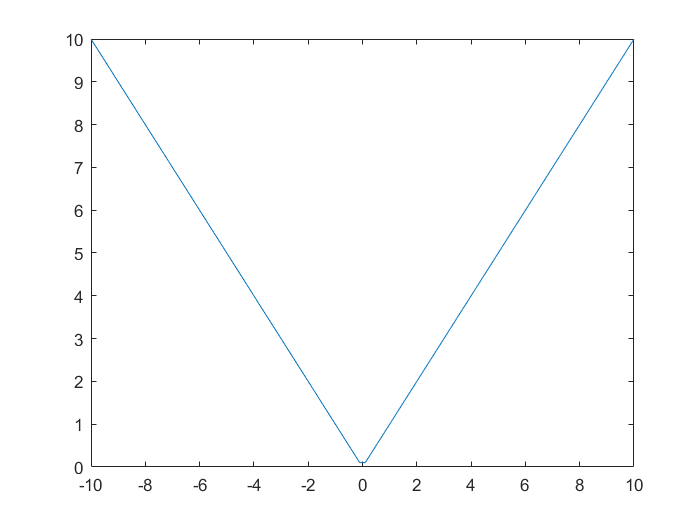

plot(x,y,'ko',x,z,'rd')

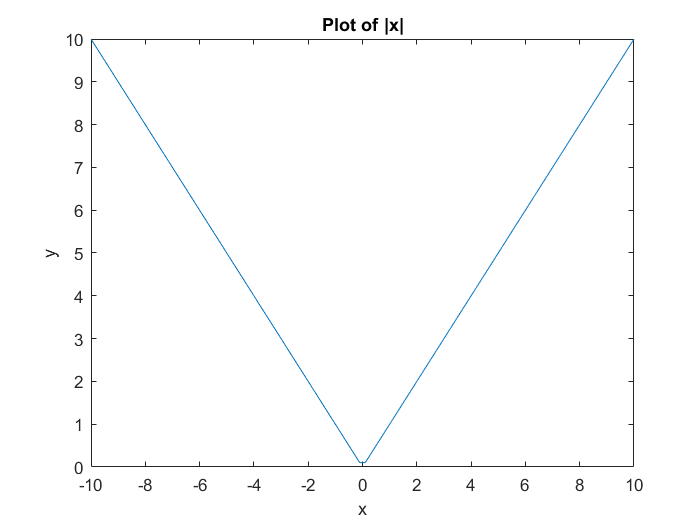

xlabel('x')
ylabel('y')
l = legend('$f(x)=x^2$','$f(x)=\sqrt{x}$',...
    'interpreter','latex','location','northwest');
title('Subplot(2,2,4)');

axis tight
% Common title for all subplots
sgtitle('Multiple plots in the same figure')

cf = gcf;
exportgraphics(cf,'mutiple_plots.pdf')

`get`, `set` and figure handles

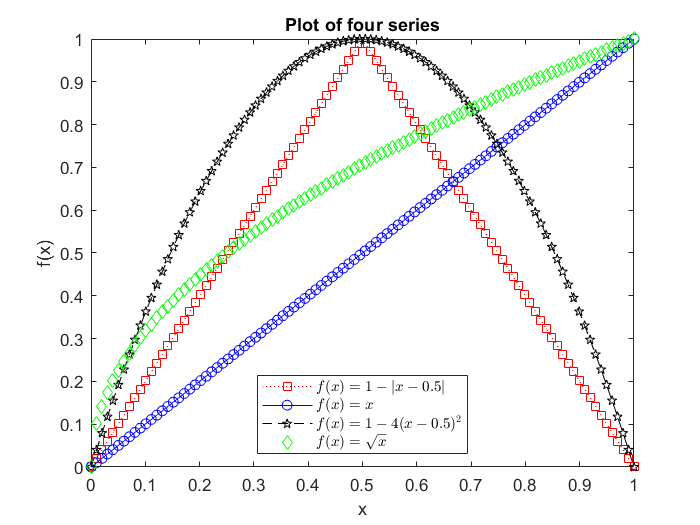

plot(randn(10,3))
% get : display properties
get(gca); % get all axes' properties
get(gca,'YTick') % get a specific property

% set : change current properties
set(gca,'YTick',-3:1:3)
set(gca,'xlim',[3 6.5])
set(gca,'linewidth',1)

% handle : properties of the appearance of the plot itself
clf 
ploth = plot(randn(10,1))
set(ploth,'LineWidth',2)
set(ploth,'Marker','o')
set(ploth,'MarkerFaceColor', 'cyan')
set(ploth,'MarkerSize',8)
set(ploth,'Color',[1 0 1])   % magenta
% Type doc ColorSpec

### 3D plotting (not covered)

Let us write the following utility function

Two ways to plot this function

- Use `fsurf` directly

% doc fsurf
% fsurf(@(x,y) utility(x,y), [0 2],'ShowContours','on')
% To see what properties are available, type
mysurf = fsurf(@(x,y) utility(x,y), [0 2],'ShowContours','on')

Of course, instead of writing a utility function in an M-file, we could have typed directly

If I'm only interested in the contour plot

% fcontour(@(x,y) utility(x,y), [ 0 2],'LineWidth',2);

-  Use `surf and/or surfc (surface plot with contours)`

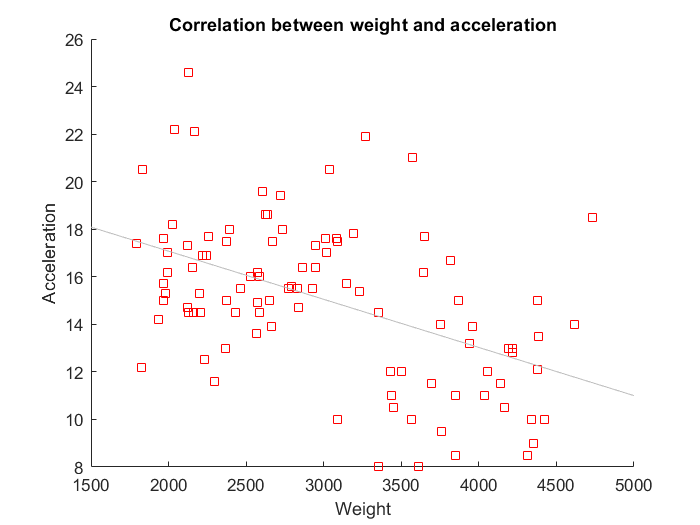

x = linspace(0,2,10);
y = linspace(0,2,10);
[X,Y] = meshgrid(x,y);     % create a net with all combinations (x,y) possible
Z = utility(X,Y);
% contour(X,Y,Z)
surfh = surf(X,Y,Z)

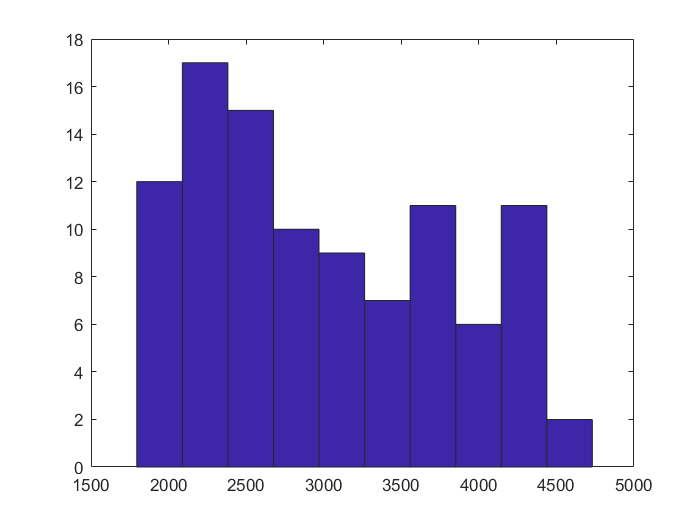

xlabel('good 1')
ylabel('good 2')
zlabel('utility')
title('Utility surface')
shading interp
% surfc(X,Y,Z)

% mesh(X,Y,Z)
% meshc(X,Y,Z)


### Exporting plots

Simplest way to export a plot: click File, Save As desired format (TIFF more MS Office, EPS or PDF for LaTeX). Figures saved in this way are of format WYSIWYG (what you see is what you get).

Figures can also be programmatically exported using `exportgraphics`

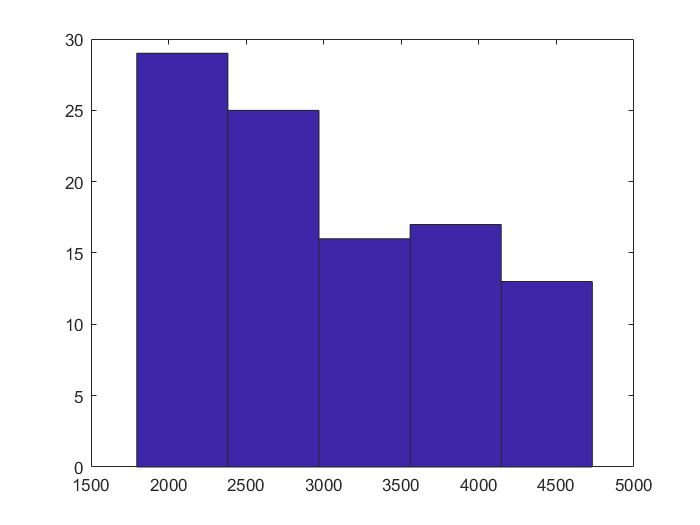

% doc exportgraphics

close
x = linspace(0,1,100);
y = 1 - abs(x - 0.5);
plot(x,y,'r')
title('Rooftop plot');
legend('f(x)=1-|x-0.5|');
xlabel('x');
ylabel('y=1-|x-0.5|');
ax = gca;                   % assign current axes to an object called 'ax'
% exportgraphics(ax, 'Rooftop.pdf')
exportgraphics(ax,'Rooftop.jpeg')
fg = gcf;
exportgraphics(fg,'Rooftop.pdf')


## Importing and exporting data

### Importing (loading) MATLAB's built-in data

### Importing external data

The best way to import data is Home -> Import Data -> auto.csv (excel file) -> Output Type (choose Table) -> Import Selection (choose Import Data) 

The code for these point-and-click operations can be generated by choosing Import Selection (choose Generate Script)

The key to import is to ensure that data in the Excel file has been formatted according to the following rules

- One variable per column

- A valid, distinct variable name for the column in the first row

- All data in the column must be either numeric or contain dates

Alternatively, it is possible to read and view data with `readtable()`. Missing variable names will be assigned `Var1`, `Var2`, etc.

% test = readtable('auto.csv')
% save test.mat

See the documentation on `table()` for more.

### Exporting data

Once the data has been loaded, it can be saved in the **.**`mat` format (MATLAB native format) using `save`

save auto

Alternatively, we can select variables to be saved

% save auto-select weight mpg
% save('auto-select','weight','mpg')

We can also save data in the format of other software. For more information:

% doc save

## Simulation and generation of random numbers

#### Four main ways to generate pseudorandom numbers in MATLAB

`rand `generates numbers from the uniform distribution on (0,1)

`randn `generates numbers from the standard normal distribution

`randg `generates numbers from the standard Gamma distribution

`randi `generates uniformly distributed pseudo random integers

M = randi(3,5);     
N = randi([0 10],5);

#### Simulation of random numbers with specified parameters

`normrnd` allows to specify the mean and standard deviation of the distribution. In the same vein, we can use `gamrnd`, `lognrnd`, `exprnd`, `unifrnd` to generate pseudo-random numbers from specific gamma, lognormal, exponential, or uniform distributions, respectively. See the Statistics and Machine Learning toolbox for more details.

mu = 5, sigma = 2;
x = normrnd(mu,sigma,100,1);
y = randn(100,1);
figure
ksdensity(x)
hold on
ksdensity(y)
hold off
grid on
legend(sprintf('Normal(%.f,%.f)',mu,sigma),'Normal(0,1)')
title('Kernel smoothing density plot')


#### Replication of simulated numbers

To replicate the simulated data `rng` can be used to remember and retrieve the seed of the simulation. This is because each simulation is assigned a 'seed' or a 'state' in MATLAB.

seedA = rng()
A = rand(3)
B = rand(3)

Note that B is generated from the seed following seedA, the seed that generates A.

rng(seedA)
C = rand(3)
D = rand(3)
% A == C
% B == D

## Exercises

#### Exercise 1. Accessing elements of a matrix

- Generate a 10-by-10 matrix of standard normal (pseudo)random numbers. Call it M

- Create the following submatrices of  M

- A matrix composed of the first two rows and the last five columns of M

- A matrix composed of rows 2 and 4 and all the columns of M

- A matrix composed of rows 2 and 4 and columns 3 and 9 of M

#### Exercise 2. Working with graphs

- Load a built-in dataset called `carsmall.`

- Type` whos('-file','carsmall.mat') `to have a look at the data.

- Are there missing values in` Weight, MPG, Horsepower, `and` Displacement? `If yes, how many? Find the exact positions (indices) of the missing values.

- Find the mean of MPG, name it meanMPG. Create a new variable called `newMPG` which is equal to `MPG` but with missing values replaced by meanMPG

- Create a scatter plot between Weight and Horsepower with Weight on the horizontal axis. Label the axis and add a title to the plot. Export this plot as `weight_vs_hp.pdf `

- Replicate the following figure

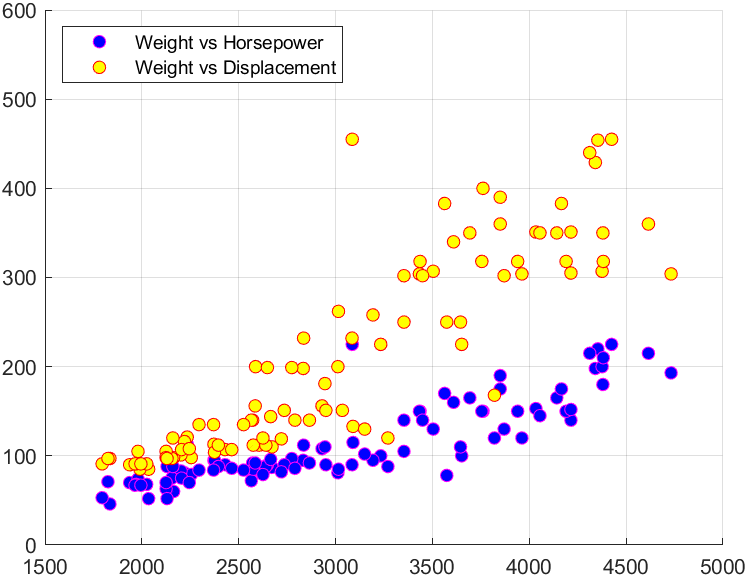

#### Exercise 3. Nonlinear optimization with linear constraints

This exercise walks you through another interesting application of MATLAB that: optimization. Let us consider a simple utility maximization problem:


$$
\max_{x_1,x_2} U(x_1,x_2) = x_1^\alpha x_2^\beta \\
\text{s.t.  } p_1 x_1 + p_ 2  x_2 \leq I$$


- Create a function called `utility(x,alpha,beta)` which takes three arguments (x is a two-dimensional vector, $\alpha \in (0,1)$ and $\beta \in (0,1)$)  and return a single utility index. Save this function in your current working directory. Test the function with different inputs to make sure that it works as expected.

- If you search for for nonlinear optimization with constraints in MATLAB, you will find that a solution is provided by `fmincon. `Type `doc fmincon `to see how to set up the problem. Notice that the piece of information that is relevant to our problem regarding the constraints is:   $Ax \leq b \\
lb \leq x  \leq ub$

- What is the matrix A and the scalar b in this case? What are the values of the upper bounds and lower bounds for each good? 

- Type

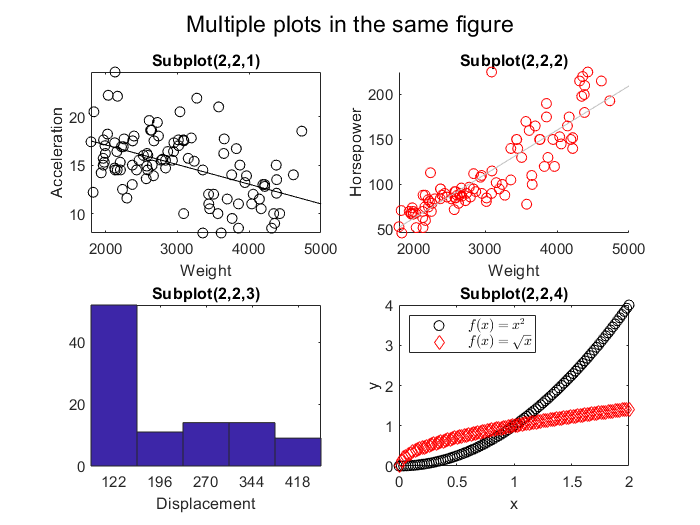

global alph bet % so that these parameters can be used globally, i.e. within the utility function once declared
alph = 0.5; bet = 0.4; income = 1000;
p1 = 1; p2 = 2*p1;
A = [p1 p2];

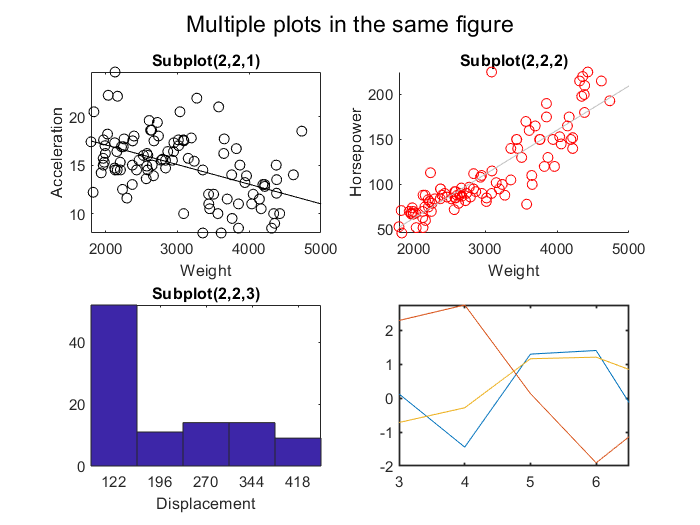

                       ALim: [0 1]
                   ALimMode: 'auto'
                 AlphaScale: 'linear'
                   Alphamap: [1×64 double]
          AmbientLightColor: [1 1 1]
               BeingDeleted: off
                        Box: on
                   BoxStyle: 'back'
                 BusyAction: 'queue'
              ButtonDownFcn: ''
                       CLim: [0 1]
                   CLimMode: 'auto'
             CameraPosition: [5 0.3763 17.3205]
         CameraPositionMode: 'auto'
               CameraTarget: [5 0.3763 0]
           CameraTargetMode: 'auto'
             CameraUpVector: [0 1 0]
         CameraUpVectorMode: 'auto'
            CameraViewAngle: 6.6086
        CameraViewAngleMode: 'auto'
                   Children: [3×1 Line]
                   Clipping: on
              ClippingStyle: '3dbox'
                      Color: [1 1 1]
                 ColorOrder: [7×3 double]
            ColorOrderIndex: 4
                 ColorScale: 'linear'
      

ans =     -2    -1     0     1     2


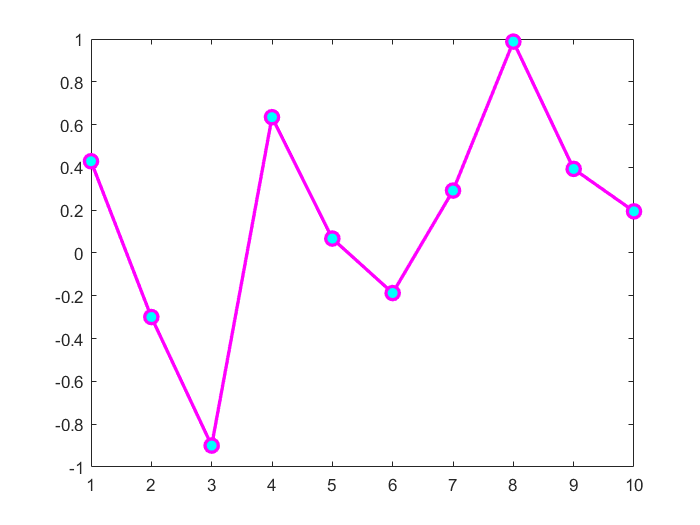

ploth =   Line with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1 2 3 4 5 6 7 8 9 10]
              YData: [0.4289 -0.2991 -0.8999 0.6347 0.0675 -0.1871 0.2917 0.9877 0.3929 0.1946]
              ZData: [1×0 double]

  Show all properties


lb = [0 0]; ub = [];
x_guess = [0 0]; %
[x,fval,exitflag] = fmincon('utility',x_guess,A,income,[],[],lb,ub)

Is the numerical solution consistent with our wellknown results for Marshallian demands for Cobb-Douglass utility functions:


$$x_1 = \frac{\alpha I}{(\alpha+\beta)p_1};\quad x_2=\frac{\beta I}{(\alpha+\beta)p_2}$$
